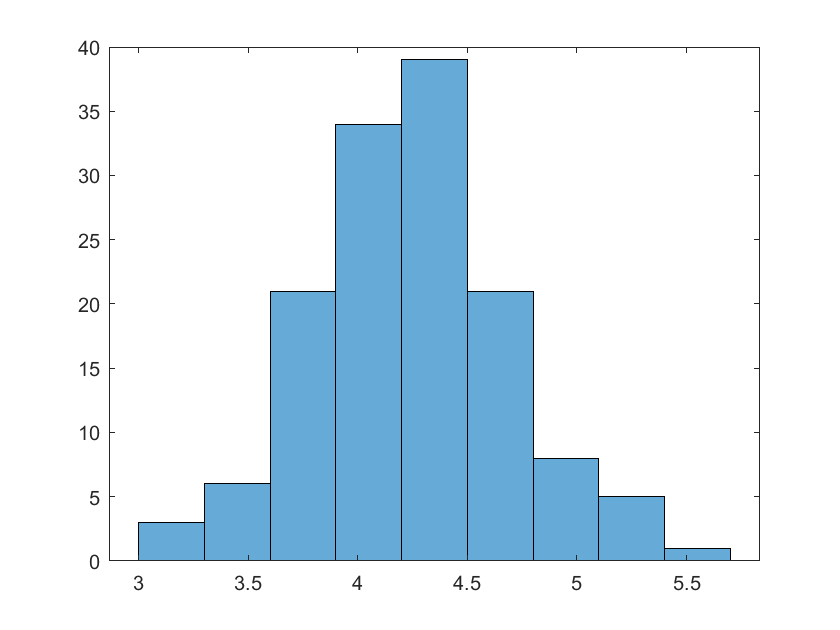

clear;clc
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\mine'
% 来，让我们先导入数据，敲键盘ing，3.96 4.23 4.42...
X=[...
    3.96	4.23	4.42	3.59	5.12	4.02	4.32	3.72	4.76	4.16	4.61	4.26...
    3.77	4.20	4.36	3.07	4.89	3.97	4.28	3.64	4.66	4.04	4.55	4.25...
    4.63	3.91	4.41	3.52	5.03	4.01	4.30	4.19	4.75	4.14	4.57	4.26...
    4.56	3.79	3.89	4.21	4.95	3.98	4.29	3.67	4.69	4.12	4.56	4.26...
    4.66	4.28	3.83	4.20	5.24	4.02	4.33	3.76	4.81	4.17	3.96	3.27...
    4.61	4.26	3.96	4.23	3.76	4.01	4.29	3.67	3.39	4.12	4.27	3.61...
    4.98	4.24	3.83	4.20	3.71	4.03	4.34	4.69	3.62	4.18	4.26	4.36...
    5.28	4.21	4.42	4.36	3.66	4.02	4.31	4.83	3.59	3.97	3.96	4.49...
    5.11	4.20	4.36	4.54	3.72	3.97	4.28	4.76	3.21	4.04	4.56	4.25...
    4.92	4.23	4.47	3.60	5.23	4.02	4.32	4.68	4.76	3.69	4.61	4.26...
    3.89	4.21	4.36	3.42	5.01	4.01	4.29	3.68	4.71	4.13	4.57	4.26...
    4.03	5.46	4.16	3.64	4.16	3.76	];
% 一长行数据
% 让我们先试试最简单的默认画法
figure (1)
h1 = histogram(X);

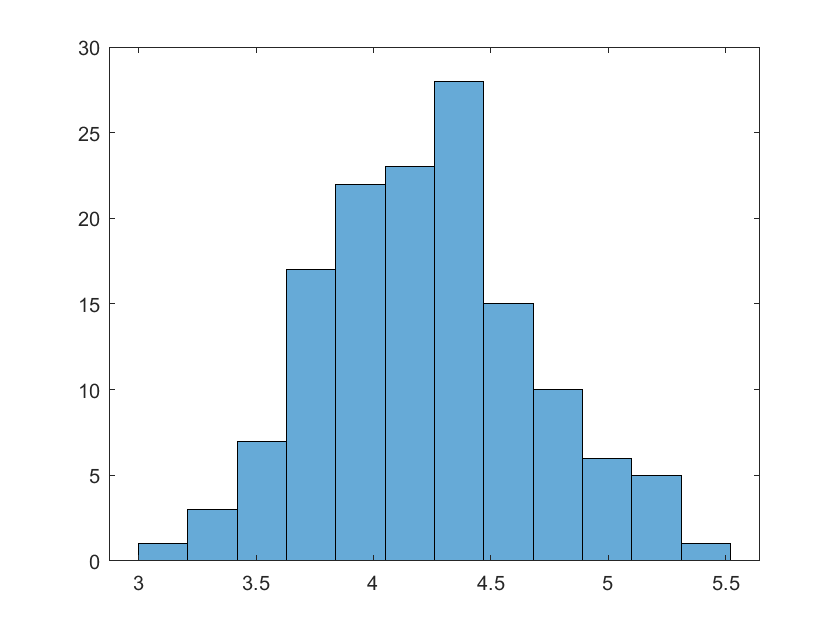

% 这可不太行，这算哪门子正态分布
% 我们必须给它制定一些限制
% 比如拿来教材的 12 组，再试一次
nbins = 12;
figure (2)
h2 = histogram(X,nbins);

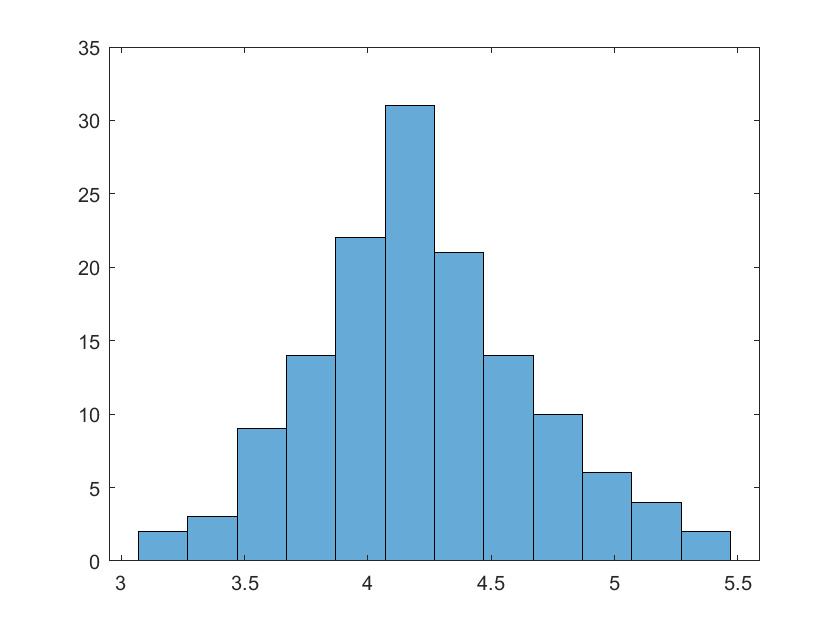

% 好一点了，但还是不行
% 合适的组数并不够，区间也需要制定合适
% 拿来教材区间，顺便验证下它画得对不对
edges = min(X):0.20:min(X)+0.2*12;  % 循环末位不能用 max(X)
figure(3)
h3 = histogram(X,edges);

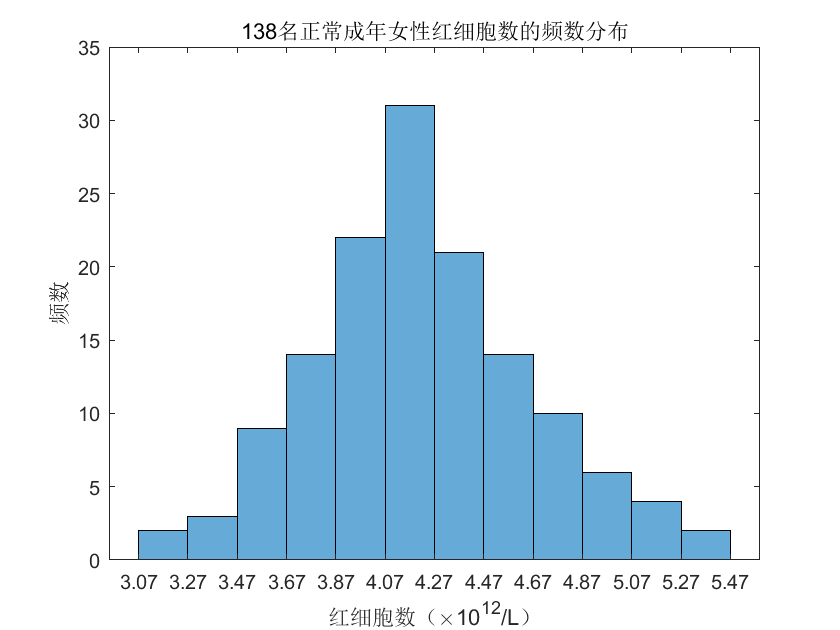

% 教材确实是对的，而且没有对比就没有伤害
% 现在要考虑的是，如何确定组数和区间
figure(4)
[h4,d,row]=hist0(X);
xlabel('红细胞数（\times10^{12}/L）'),ylabel('频数')
title([num2str(length(X)) '名正常成年女性红细胞数的频数分布'])